cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_28_realisticScatter')
load('aveSOS&steSOS&tofcell&rateEMCLs')
load('transducer_2board')

到達点ズレ情報の配列を作成．

r_num = t_num/2;
diff_point_each = zeros(r_num, length(aveSOS));
for ii = 1:length(aveSOS)
    [Min ,ind] = min(tof_cell(101:200,:,ii),[],1);
    for jj = 1:r_num
        diff_point_each(jj,ii) = (ind(1,jj) - jj);
    end
end

経路変化分の分散を見る．

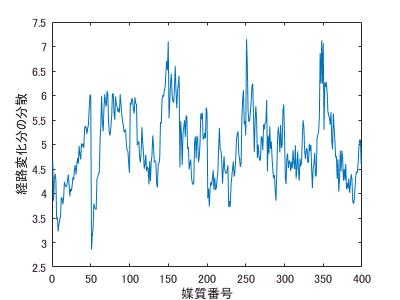

w = 1;
y = std(diff_point_each,w,1);
figure;
plot(y);
xlabel('媒質番号')
ylabel('経路変化分の分散')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_03_analyze400RealisticModels')
exportfig('diviation_path_diff','png',[400,300]);

EMCL率のプロットを作る．

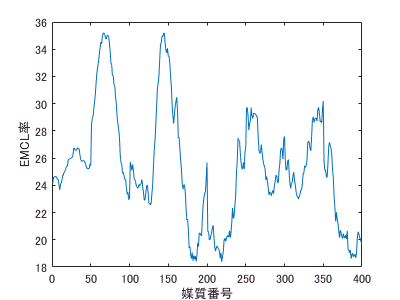

figure;
plot(rate_EMCLs);
xlabel('媒質番号')
ylabel('EMCL率')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_03_analyze400RealisticModels')
exportfig('rate_EMCL','png',[400,300]);

平均音速値のプロットを作る．

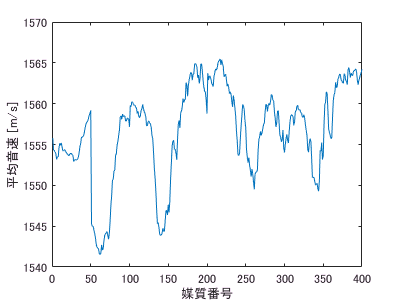

figure;
plot(aveSOS);
xlabel('媒質番号')
ylabel('平均音速 [m/s]')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_03_analyze400RealisticModels')
exportfig('aveSOS2','png',[400,300]);

相関係数 x~y, y~z, z~xを出すにあたり，これらの散布図を用意する．z

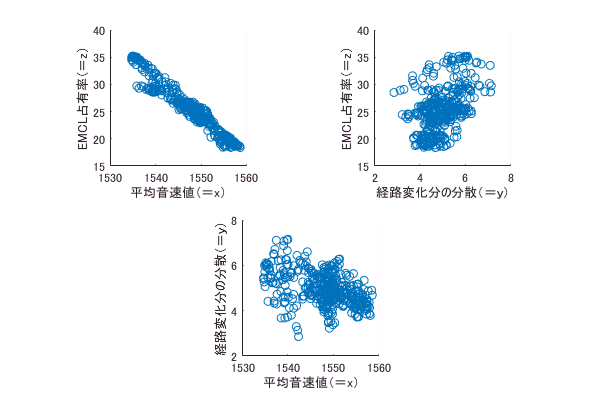

x = aveSOS2;
y = std(diff_point_each,w,1);
z = rate_EMCLs;

figure;
subplot(2,2,1);
scatter(x,z);
xlabel('平均音速値（＝x）')
ylabel('EMCL占有率（＝z）')
axis square;
subplot(2,2,2);
scatter(y,z);
xlabel('経路変化分の分散（＝ｙ）')
ylabel('EMCL占有率（＝z）')
axis square;
subplot(2,2,[3 4]);
scatter(x,y);
xlabel('平均音速値（＝x）')
ylabel('経路変化分の分散（＝ｙ）')
axis square;
hold off
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_03_analyze400RealisticModels')
exportfig('correlation','png',[600,400]);

全組み合わせの共分散を出す．

sxy = cov(x,y,w);
sxy = sxy(1,2)

sxy = -2.0096

szx = cov(z,x,w);
szx = szx(1,2)

szx = -24.5064

szy = cov(z,y,w);
szy = szy(1,2)

szy = 1.4460

全組み合わせの標準偏差を出す

w = 1;
sx = std(x,w,2)

sx = 6.0513

sy = std(y,w,2)

sy = 0.7374

sz = std(z,w,2)

sz = 4.1796

sx2 = sx^2 

sx2 = 36.6177

sy2 = sy^2

sy2 = 0.5437

sz2 = sz^2

sz2 = 17.4688

各変数同士の相関係数を求める．

rxy = sxy/(sx*sy)

rxy = -0.4504

rzx = szx/(sz*sx)

rzx = -0.9690

rzy = szy/(sz*sy)

rzy = 0.4692

各変数の平均値を求める．

x_ave = mean(x)

x_ave = 1.5479e+03

y_ave = mean(y)

y_ave = 4.9571

z_ave = mean(z)

z_ave = 25.3367

重回帰を行う．

２種類の回帰方程式(単回帰方程式と平面回帰方程式)とｘとの相関係数を比較する．

そのために重回帰方程式を求める．　z2 = ax + by + cとする．

単回帰方程式においてはすでにrzxで相関係数が出ている．

a = (szx*sy^2 - sxy*szy) / (sx^2*sy^2 - sxy^2)

a = -0.6564

b = (sx^2*szy - sxy*szx) / (sx^2*sy^2 - sxy^2)

b = 0.2333

c = (mean(z) - a*mean(x) - b*mean(y))

c = 1.0403e+03

z2 = a*x + b*y + c;
u = a*x + b*y;
szx

szx = -24.5064

szy

szy = 1.4460

sxy

sxy = -2.0096

rzu = sqrt((a*szx+b*szy)/sz^2)

rzu = 0.9696

減衰率